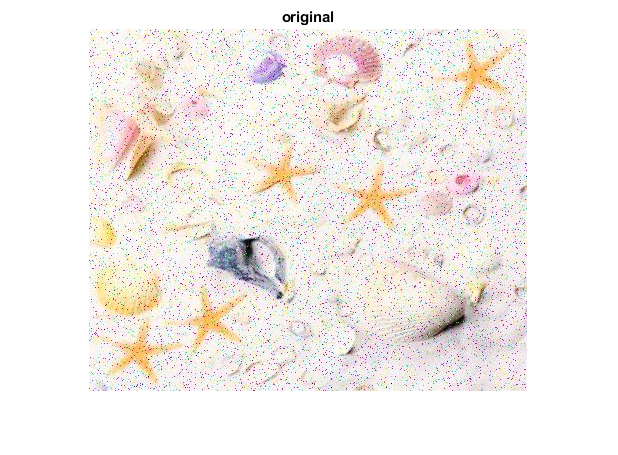

clear
% % %

im = imread("images\starfish.jpg");
imshow(im);
title("original");

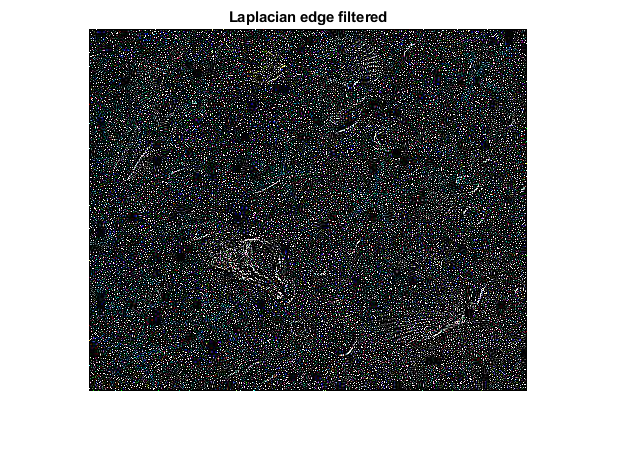

oim = im;
w = [1 1 1; 1 -8 1; 1 1 1]; % 3x3 laplacian

c = 2;
r = 5;
n = 0;

%  Laplacian edge filter
im1 = imfilter(im, w);
imshow(im1)
title("Laplacian edge filtered");

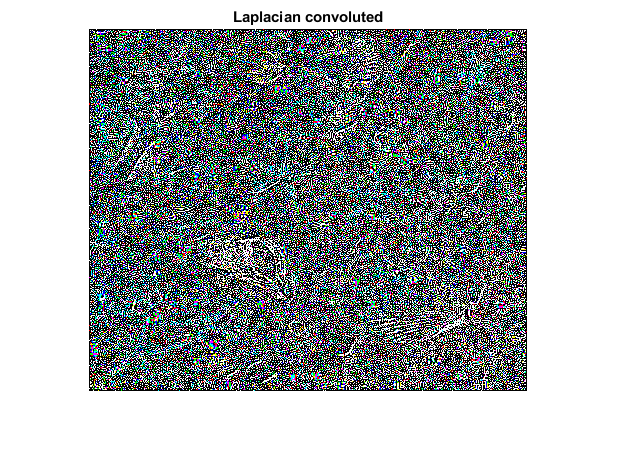

%  Laplacian edge filter CONVOLUTION
im2 = convn(im, w, 'same');
imshow(im2)
title("Laplacian convoluted");

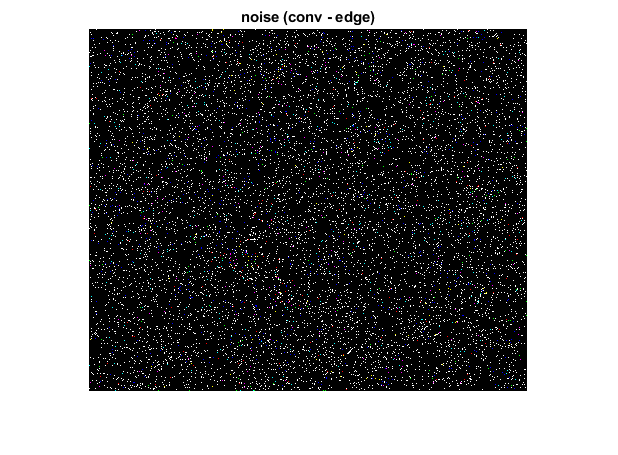

%  DIFFERENCE between edges and convolution
noise = double(im2) - double(im1);
imshow(noise)
title("noise (conv - edge)");


% Split noise channels
[n1,n2,n3] = imsplit(noise);
n1 = n1 > 0;
n1NoiseLevel = (100/sum(n1(:)))

n1NoiseLevel = 0.0118

n2 = n2 > 0;
n2NoiseLevel = (100/sum(n2(:)))

n2NoiseLevel = 0.0117

n3 = n3 > 0;
n3NoiseLevel = (100/sum(n3(:)))

n3NoiseLevel = 0.0110

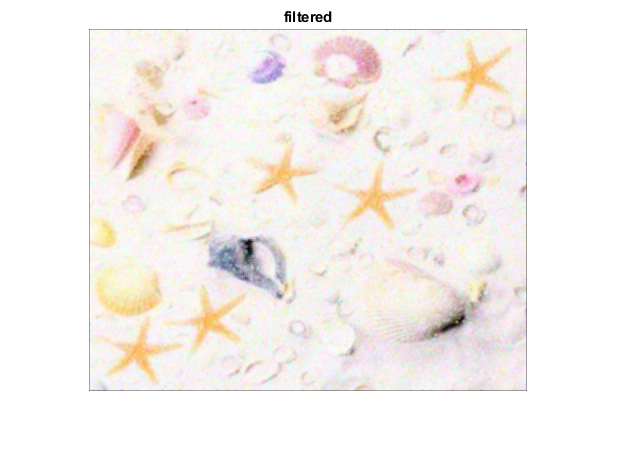


% % (a) set to white
filtered = oim;
[f1,f2,f3] = imsplit(filtered);
f1(n1) = 255;
% f1 = medfilt2(f1);
f1 = imfilter(f1, ones(3)/9, 'same');
f2(n2) = 255;
% f2 = medfilt2(f2);
f2 = imfilter(f2, ones(3)/9, 'same');
f3(n3) = 255;
% f3 = medfilt2(f3);
f3 = imfilter(f3, ones(3)/9, 'same');
filtered = cat(3, f1, f2, f3);
imshow(filtered);
title("filtered");

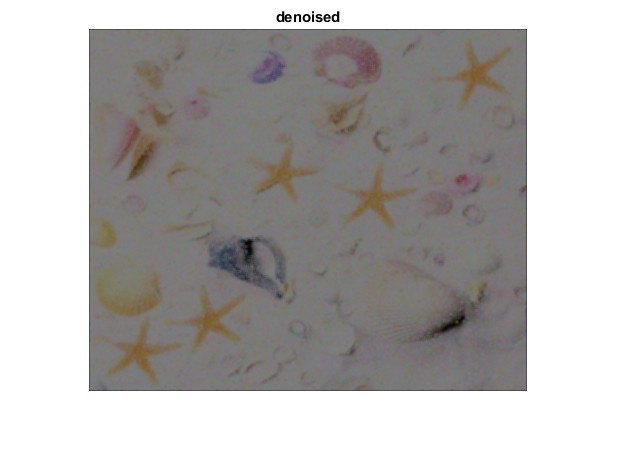


% % (b) filter
% filtered = oim;
% [f1,f2,f3] = imsplit(filtered);
% f1 = medfilt2(f1);
% f2 = medfilt2(f2);
% f3 = medfilt2(f3);
% filtered = cat(3, f1, f2, f3);
% imshow(filtered);
% title("filtered");

% Denoise channels
[c1d,c2d,c3d] = imsplit(filtered);
c1d(n1) = f1(n1);
c2d(n2) = f2(n2);
c3d(n3) = f3(n3);
denoised = cat(3, c1d,c2d,c3d) / 2;
imshow(denoised);
title("denoised");

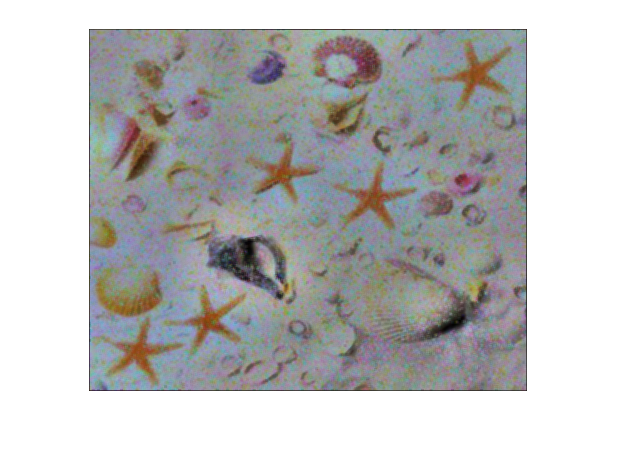


% Enhance contrast.
[c1,c2,c3] = imsplit(denoised);
c1 = adapthisteq(c1);
c2 = adapthisteq(c2);
c3 = adapthisteq(c3);
ce = cat(3,c1,c2,c3);
imshow(ce);


% figure
% % Edge detection.
% subplot(r,c, (n + 1));
% im = imfilter(im, w);
% imshow(im);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(im);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c1 = imfilter(c1, w);
% imshow(c1);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c1);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c2 = imfilter(c2, w);
% imshow(c2);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c2);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c3 = imfilter(c3, w);
% imshow(c3);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c3);